% % Save arrays of the x and y coordinates
% x_positions_array = (h.x / 10) + 5.664; % is in cm now
% output_dir = 'D:\Matlab\Matlab output\3D_matrices_surface_height\\';
% output_file_x = fullfile(output_dir, 'x_positions_array_full_plate.mat');
% save(output_file_x, 'x_positions_array');

% y_positions_array = (h.y + 594.001000000000)/10; % is in cm now
% output_dir = 'D:\Matlab\Matlab output\3D_matrices_surface_height\\';
% output_file_y = fullfile(output_dir, 'y_positions_array_full_plate.mat');
% save(output_file_y, 'y_positions_array');

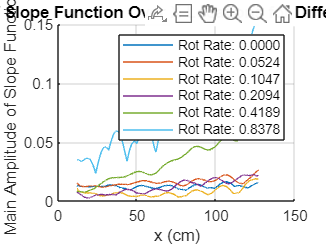

% Clear previous variables and figures
clear 
close all
clc

%date = '09';
freq_value = 2.2; % Frequency value (unchanged)
ampl_value = 7;   % Amplitude value (unchanged)
freq_value = string(freq_value);
ampl_value = string(ampl_value);

% File path for the data files
file_path = 'D:\Matlab\Matlab output\3D_matrices_surface_height\';

% Define the array of rotation rates to analyze
rot_rates = [0, 0.0524, 0.1047, 0.2094, 0.4189, 0.8378];

% Prepare to plot the main amplitude over x positions for each rot_rate
figure; hold on; % Hold on to plot multiple lines

% Loop over each rotation rate
for r = 1:length(rot_rates)
    rot_rate = rot_rates(r); % Current rotation rate
    rot_rate_str = string(rot_rate);
    
    % Load the surface height data for the current rotation rate
    surface_height_file = [file_path sprintf('surface_height_3D_%sradps_%sHz_%smm_full_plate.mat', rot_rate_str, freq_value, ampl_value)];
    data = load(surface_height_file);
    surface_height_3D = data.surface_height_3D; % 3D matrix (x, y, time)

    % Load the x and y coordinate arrays
    x_positions_file = [file_path 'x_positions_array_full_plate.mat'];
    y_positions_file = [file_path 'y_positions_array_full_plate.mat'];

    x_data = load(x_positions_file);
    y_data = load(y_positions_file);

    x_positions = x_data.x_positions_array; % Array of x positions
    y_positions = y_data.y_positions_array; % Array of y positions

    % Get the dimensions of the 3D surface height data
    [num_x, num_y, num_time] = size(surface_height_3D);

    % Time vector: Assuming the time step is uniform and given by the z-dimension
    T = 1; % Total duration (adjust if needed)
    dt = T / num_time; % Time step size
    time_vector = 0:dt:(T-dt); % Time vector

    % Initialize an array to store the main amplitude of the slope function at each x location
    amplitude_over_x = zeros(1, num_x);

    % Loop over every x location
    for i = 1:num_x
        % Initialize an array to store the slopes for all time stamps at this x location
        slopes_over_time = zeros(1, num_time);
        
        % Loop over each time stamp
        for t = 1:num_time
            % Get the surface height data at the current x location and time stamp over y-axis
            surface_height_y = squeeze(surface_height_3D(i, :, t)); % Extract 1D array over y-axis
            
            % Perform linear fit (1st-degree polynomial) using polyfit
            p = polyfit(y_positions, surface_height_y, 1);
            
            % p(1) is the slope of the fitted line
            slopes_over_time(t) = p(1);
        end
        
        % Perform Fourier transform on the slope function over time
        slope_fft = fft(slopes_over_time);
        
        % Compute the amplitude spectrum
        slope_amplitude = 2 * abs(slope_fft / num_time); % Normalize the amplitude
        slope_amplitude = slope_amplitude(1:floor(num_time/2)); % Take the first half of the FFT (positive frequencies)
        
        % Store the main amplitude (usually the peak of the Fourier transform) for this x position
        [~, max_idx] = max(slope_amplitude); % Find the frequency with the highest amplitude
        amplitude_over_x(i) = slope_amplitude(max_idx); % Store the max amplitude
    end

    % Plot the main amplitude of the slope function over x positions for current rotation rate
    plot(x_positions, amplitude_over_x, 'DisplayName', sprintf('Rot Rate: %.4f', rot_rate)); % Add label for legend
end

% Add labels, title, and grid to the plot
xlabel('x (cm)');
ylabel('Main Amplitude of Slope Function');
title('Main Amplitude of Slope Function Over X Locations for Different Rotational Rates');
grid on;
legend show; % Show legend to distinguish different rotation rates
hold off; % Release hold

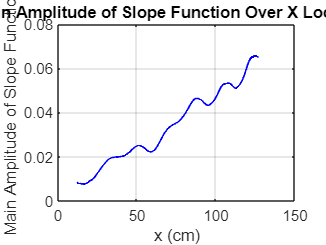

clear 
close all
clc

date = '09';
rot_rate = 0.4189;
rot_rate = string(rot_rate);
freq_value = 2.2;
freq_value = string(freq_value);
ampl_value = 7;
ampl_value = string(ampl_value);

% File path for the data files
file_path = 'D:\Matlab\Matlab output\3D_matrices_surface_height\';

% Load the surface height data
surface_height_file = [file_path sprintf('surface_height_3D_%s_%sradps_%sHz_%smm_full_plate.mat', date, rot_rate, freq_value, ampl_value)];
data = load(surface_height_file);
surface_height_3D = data.surface_height_3D; % 3D matrix (x, y, time)

% Load the x and y coordinate arrays
x_positions_file = [file_path 'x_positions_array_full_plate.mat'];
y_positions_file = [file_path 'y_positions_array_full_plate.mat'];

x_data = load(x_positions_file);
y_data = load(y_positions_file);

x_positions = x_data.x_positions_array; % Array of x positions
y_positions = y_data.y_positions_array; % Array of y positions

% Get the dimensions of the 3D surface height data
[num_x, num_y, num_time] = size(surface_height_3D);

% Time vector: Assuming the time step is uniform and given by the z-dimension
% Adjust the time step 'dt' and duration 'T' if necessary
T = 1; % Total duration (adjust if needed)
dt = T / num_time; % Time step size
time_vector = 0:dt:(T-dt); % Time vector

% Initialize an array to store the main amplitude of the slope function at each x location
amplitude_over_x = zeros(1, num_x);

% Loop over every x location
for i = 1:num_x
    % Initialize an array to store the slopes for all time stamps at this x location
    slopes_over_time = zeros(1, num_time);
    
    % Loop over each time stamp
    for t = 1:num_time
        % Get the surface height data at the current x location and time stamp over y-axis
        surface_height_y = squeeze(surface_height_3D(i, :, t)); % Extract 1D array over y-axis
        
        % Perform linear fit (1st-degree polynomial) using polyfit
        p = polyfit(y_positions, surface_height_y, 1);
        
        % p(1) is the slope of the fitted line
        slopes_over_time(t) = p(1);
    end
    
    % Perform Fourier transform on the slope function over time
    slope_fft = fft(slopes_over_time);
    
    % Compute the amplitude spectrum
    slope_amplitude = 2*abs(slope_fft/ num_time); % Normalize the amplitude
    slope_amplitude = slope_amplitude(1:floor(num_time/2)); % Take the first half of the FFT (positive frequencies)
    
    % Store the main amplitude (usually the peak of the Fourier transform) for this x position
    [~, max_idx] = max(slope_amplitude); % Find the frequency with the highest amplitude
    amplitude_over_x(i) = slope_amplitude(max_idx); % Store the max amplitude
end

% Plot the main amplitude of the slope function over x positions
figure;
plot(x_positions, amplitude_over_x, 'b', 'LineWidth', 1);
xlabel('x (cm)');
ylabel('Main Amplitude of Slope Function');
title('Main Amplitude of Slope Function Over X Locations');
grid on;

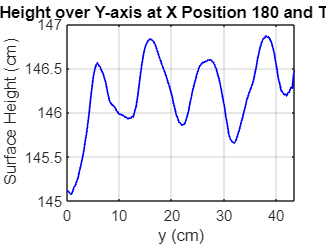

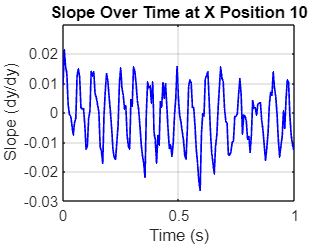

% Choose a specific x position and time step for visualization
x_index = 180;   % Index of x position (choose a number between 1 and length of x_positions)
time_index = 155; % Index of time step (choose a number between 1 and num_time)

% Extract the surface height data at the chosen x position and time step
surface_height_y = squeeze(surface_height_3D(x_index, :, time_index)); % Extract the data along y-axis

% Plot the surface height as a function of y coordinates
figure;
plot(y_positions, surface_height_y, 'b', 'LineWidth', 1);
xlabel('y (cm)');
ylabel('Surface Height (cm)');
title(sprintf('Surface Height over Y-axis at X Position %d and Time Step %d', x_index, time_index));
grid on;

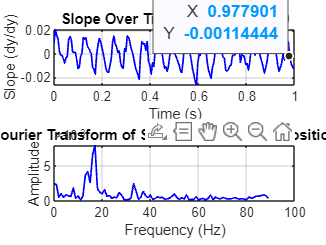

% Clear previous variables and figures
clear 
close all
clc

date = '09';
rot_rate = 0.4189;
rot_rate = string(rot_rate);
freq_value = 2.2;
freq_value = string(freq_value);
ampl_value = 7;
ampl_value = string(ampl_value);

% File path for the data files
file_path = 'D:\Matlab\Matlab output\3D_matrices_surface_height\';

% Load the surface height data
surface_height_file = [file_path sprintf('surface_height_3D_%s_%sradps_%sHz_%smm_full_plate.mat', date, rot_rate, freq_value, ampl_value)];
data = load(surface_height_file);
surface_height_3D = data.surface_height_3D; % 3D matrix (x, y, time)

% Load the x and y coordinate arrays
x_positions_file = [file_path 'x_positions_array_full_plate.mat'];
y_positions_file = [file_path 'y_positions_array_full_plate.mat'];

x_data = load(x_positions_file);
y_data = load(y_positions_file);

x_positions = x_data.x_positions_array; % Array of x positions
y_positions = y_data.y_positions_array; % Array of y positions

% Get the dimensions of the 3D surface height data
[num_x, num_y, num_time] = size(surface_height_3D);

% Time vector: Assuming the time step is uniform and given by the z-dimension
% Adjust the time step 'dt' and duration 'T' if necessary
T = 1; % Total duration (adjust if needed)
dt = T / num_time; % Time step size
time_vector = 0:dt:(T-dt); % Time vector

% Choose a specific x position for slope visualization
x_index = 10;   % Index of x position (choose a number between 1 and length of x_positions)

% Initialize an array to store the slopes for all time steps at the chosen x position
slopes_over_time = zeros(1, num_time);

% Loop over each time step to calculate the slope using polyfit
for t = 1:num_time
    % Get the surface height data at the current x position and time stamp over y-axis
    surface_height_y = squeeze(surface_height_3D(x_index, :, t)); % Extract 1D array over y-axis
    
    % Perform linear fit (1st-degree polynomial) using polyfit
    p = polyfit(y_positions, surface_height_y, 1);
    
    % p(1) is the slope of the fitted line
    slopes_over_time(t) = p(1);
end

% Plot the slopes as a function of time with smaller circles
figure;
subplot(2, 1, 1); % Create a subplot for slope over time
plot(time_vector, slopes_over_time, 'b', 'LineWidth', 1); % Set 'MarkerSize' to a smaller value (e.g., 3)
xlabel('Time (s)');
ylabel('Slope (dy/dy)');
title(sprintf('Slope Over Time at X Position %d', x_index));
grid on;

% Calculate the Fourier Transform of the slopes
slope_fft = fft(slopes_over_time);
slope_amplitude = 2*abs(slope_fft/ num_time); % Normalize the amplitude
slope_amplitude = slope_amplitude(1:floor(num_time/2)); % Keep only the positive frequencies

% Frequency vector for plotting
frequencies = (0:floor(num_time/2)-1) / (num_time * dt); % Frequency vector based on time step

% Plot the Fourier Transform (amplitude spectrum)
subplot(2, 1, 2); % Create a second subplot for the Fourier Transform
plot(frequencies, slope_amplitude, 'b', 'LineWidth', 1);
xlabel('Frequency (Hz)');
ylabel('Amplitude');
title(sprintf('Fourier Transform of Slope Function at X Position %d', x_index));
grid on;

frame_rate = 23.98;  % Frame rate in frames per second

%% Initialize array to store slopes for each frame
slopes_over_time = zeros(end_frame - start_frame + 1, 1);

%% Calculate time in seconds for each frame
% frame_numbers = start_frame:end_frame;
% time_in_seconds = (frame_numbers - 1) / frame_rate;
frame_numbers = 1:156;
time_in_seconds = (frame_numbers - 1) / frame_rate;

%% Iterate over each frame to calculate the slope for the selected long axis point
for frame_num = start_frame:end_frame
    % Construct the file name for the current frame
    frame_str = sprintf('%04d', frame_num);
    file_name = [base_file_name, frame_str, file_extension];
    input_file = fullfile(input_dir, file_name);

    % Load the data
    dr = loadvec(input_file);

    % Process the data: remove rows and columns with only zeros
    dr_new = dr;
    dr_new.x(:, all(dr_new.vy == 0, 2)) = [];
    dr_new.y(:, all(dr_new.vy == 0, 1)) = [];
    dr_new.vx(:, all(dr_new.vx == 0, 1)) = [];
    dr_new.vx(all(dr_new.vx == 0, 2), :) = [];
    dr_new.vy(:, all(dr_new.vy == 0, 1)) = [];
    dr_new.vy(all(dr_new.vy == 0, 2), :) = [];

    % Compute the surface height
    h_0 = 150; % Surface-pattern distance in mm
    h = surfheight(dr_new, h_0);
    surface_height = h.w;

    % Surface height on short axis for the selected long axis point
    surf_height_short_axis = surface_height(selected_long_axis_point, :);
    ampl_short_axis = surf_height_short_axis;
    values_short_axis = h.y / 10;  % Convert to cm

    % Linear fit for slope calculation
    p = polyfit(values_short_axis, ampl_short_axis, 1);  
    slopes_over_time(frame_num - start_frame + 1) = p(1);  % Store the slope
end

%% Plot slopes over time (in seconds)
plot(time_in_seconds, slopes_over_time, 'b', 'LineWidth', 2);
%title(sprintf('Slope of surface height %sradps %sHz %smm pos %d', rot_rate, freq_value, string(ampl_value), selected_long_axis_point));
xlabel('Time (sec)');
ylabel('Slope of surface height');
ax = gca; % Get current axes
ax.YAxis.TickLabelFormat = '%.2f'; % Display numbers in decimal format with 3 decimal places
xlim([0,7])
ylim([-0.15,0.15])
ax.FontSize = 15;
grid on;

% %% Compute Peak-to-Peak Amplitude
% max_slope = max(slopes_over_time);  % Maximum slope value
% min_slope = min(slopes_over_time);  % Minimum slope value
% peak_to_peak_amplitude = max_slope - min_slope;
% fprintf('Peak-to-Peak Amplitude: %.4f\n', peak_to_peak_amplitude);
% 
% %% Compute RMS Amplitude
% rms_amplitude = rms(slopes_over_time);  % Root Mean Square of the slopes
% %% Compute Standard Deviation of Slopes
% slope_std_dev = std(slopes_over_time);  % Standard deviation of slope values
% 
% %% Compute Standard Error of RMS (SERMS)
% N = length(slopes_over_time);  % Number of frames
% serms = slope_std_dev / sqrt(N);  % Standard error of the RMS amplitude
% 
% %% Display the values
% fprintf('RMS Amplitude: %.4f\n', rms_amplitude);
% fprintf('Standard Deviation of Slopes: %.4f\n', slope_std_dev);
% fprintf('Standard Error of RMS Amplitude (SERMS): %.4f\n', serms);

%% Save the plot
print(gcf,'-depsc', fullfile(output_dir, sprintf('%sradps_%sHz_%smm_pos_%d_slope_over_time.eps', rot_rate, freq_value, string(ampl_value), selected_long_axis_point)));
saveas(gcf, fullfile(output_dir, sprintf('%sradps_%sHz_%smm_pos_%d_slope_over_time.png', rot_rate, freq_value, string(ampl_value), selected_long_axis_point)));

toc;


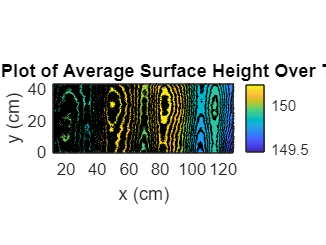

% To plot the average surface height

clear 
close all
clc

date = '09';
rot_rate = 0.4189;
rot_rate = string(rot_rate);
freq_value = 2.2;
freq_value = string(freq_value);
ampl_value = 7;
ampl_value = string(ampl_value);

% File path for the data files
file_path = 'D:\Matlab\Matlab output\3D_matrices_surface_height\';

% Load the surface height data
surface_height_file = [file_path sprintf('surface_height_3D_%s_%sradps_%sHz_%smm_full_plate.mat', date, rot_rate, freq_value, ampl_value)];
data = load(surface_height_file);
surface_height_3D = data.surface_height_3D;

% Load the x and y coordinate arrays
x_positions_file = [file_path 'x_positions_array_full_plate.mat'];
y_positions_file = [file_path 'y_positions_array_full_plate.mat'];

x_data = load(x_positions_file);
y_data = load(y_positions_file);

x_positions = x_data.x_positions_array;
y_positions = y_data.y_positions_array;

% Calculate the average surface height over time (3rd dimension)
average_surface_height = mean(surface_height_3D, 3);
average_surface_height = average_surface_height';

% Create a meshgrid using the x and y positions (ensure dimensions match)
[X, Y] = meshgrid(x_positions, y_positions);

% Create a filled contour plot of the average surface height
figure;
contourf(X, Y, average_surface_height, 20); % 20 contour levels
axis equal
xlabel('x (cm)');
ylabel('y (cm)');
ax = gca; % Get current axes
ax.FontSize = 10;
title('Contour Plot of Average Surface Height Over Time');
colorbar; % Display color scale

% % Start timing
% tic;
% 
% clear;
% close all;
% clc;
% 
% % Define the input parameters for each combination of date, rot_rate, ampl_value, and corresponding start and end frames
% input_parameters = {
%     '10', 0, 3, 170, 350;     % Format: 'date', rot_rate, ampl_value, start_frame, end_frame
%     '10', 0, 5, 170, 350;
%     '10', 0, 7, 170, 325;
%     '10', 0, 9, 200, 350;
%     '10', 0.0524, 3, 170, 300;
%     '10', 0.0524, 5, 170, 300;
%     '10', 0.0524, 7, 170, 300;
%     '10', 0.0524, 9, 200, 350;
%     '09', 0.1047, 3, 170, 375;   
%     '09', 0.1047, 5, 150, 300;   
%     '09', 0.1047, 7, 170, 350;   
%     '09', 0.1047, 9, 170, 350;   
%     '10', 0.2094, 3, 200, 400;   
%     '10', 0.2094, 5, 170, 300;  
%     '10', 0.2094, 7, 170, 350;  
%     '10', 0.2094, 9, 170, 300;   
%     '09', 0.4189, 3, 200, 400;  
%     '09', 0.4189, 5, 170, 350;   
%     '09', 0.4189, 7, 170, 350;  
%     '09', 0.4189, 9, 200, 350;  
%     '09', 0.8378, 3, 170, 350;   
%     '09', 0.8378, 5, 170, 350;   
%     '09', 0.8378, 7, 170, 350;  
%     '09', 0.8378, 9, 170, 300;   
% };
% %% Define frequency value (assuming it stays constant)
% freq_value = 2.2;
% freq_value = string(freq_value);
% selected_long_axis_point = 170;  % Point on long axis to monitor over time
% frame_rate = 23.98;  % Frame rate in frames per second
% 
% % Initialize a table to store results
% results = table('Size', [0 5], 'VariableTypes', {'string', 'double', 'double', 'double', 'double'}, ...
%                 'VariableNames', {'Date', 'RotRate', 'AmplValue', 'RMS_Amplitude', 'Standard_Error'});
% 
% % Loop through all the input parameter combinations
% for i = 1:size(input_parameters, 1)
%     date = input_parameters{i, 1};
%     rot_rate = input_parameters{i, 2};
%     ampl_value = input_parameters{i, 3};
%     start_frame = input_parameters{i, 4};
%     end_frame = input_parameters{i, 5};
% 
%     % Define the base directory for input and output files
%     input_dir = sprintf('D:\\Matlab\\Matlab input\\202409%s_full_plate_final\\202409%s_%sradps_%sHz_%smm_full_plate_separate_frames\\Results\\', ...
%                         date, date, string(rot_rate), freq_value, string(ampl_value));
% 
%     % Define the base file name and extension
%     base_file_name = sprintf('202409%s_%sradps_%sHz_%smm_full_plate_frame_', date, string(rot_rate), string(freq_value), string(ampl_value));
%     file_extension = 'A_vel_new.dat';
% 
%     % Initialize array to store slopes for each frame
%     slopes_over_time = zeros(end_frame - start_frame + 1, 1);
% 
%     % Iterate over each frame to calculate the slope for the selected long axis point
%     for frame_num = start_frame:end_frame
%         % Construct the file name for the current frame
%         frame_str = sprintf('%04d', frame_num);
%         file_name = [base_file_name, frame_str, file_extension];
%         input_file = fullfile(input_dir, file_name);
% 
%         % Load the data
%         dr = loadvec(input_file);
% 
%         % Process the data: remove rows and columns with only zeros
%         dr_new = dr;
%         dr_new.x(:, all(dr_new.vy == 0, 2)) = [];
%         dr_new.y(:, all(dr_new.vy == 0, 1)) = [];
%         dr_new.vx(:, all(dr_new.vx == 0, 1)) = [];
%         dr_new.vx(all(dr_new.vx == 0, 2), :) = [];
%         dr_new.vy(:, all(dr_new.vy == 0, 1)) = [];
%         dr_new.vy(all(dr_new.vy == 0, 2), :) = [];
% 
%         % Compute the surface height
%         h_0 = 150; % surface-pattern distance in mm
%         h = surfheight(dr_new, h_0);
%         surface_height = h.w;
% 
%         % Surface height on short axis for the selected long axis point
%         surf_height_short_axis = surface_height(selected_long_axis_point, :);
%         ampl_short_axis = surf_height_short_axis;
%         values_short_axis = h.y / 10;  % Convert to cm
% 
%         % Linear fit for slope calculation
%         p = polyfit(values_short_axis, ampl_short_axis, 1);  
%         slopes_over_time(frame_num - start_frame + 1) = p(1);  % Store the slope
%     end
% 
%     % Calculate RMS amplitude and standard error for this combination
%     rms_amplitude = sqrt(mean(slopes_over_time.^2));  % RMS amplitude
%     standard_error = std(slopes_over_time) / sqrt(length(slopes_over_time));  % Standard error
% 
%     % Store the results in the table
%     new_row = {date, rot_rate, ampl_value, rms_amplitude, standard_error};
%     results = [results; new_row];
% end
% 
% % Save the table to a CSV file
% output_dir = 'D:\Matlab\Matlab output\RMS_Results\';  % Desired folder for saving
% if ~exist(output_dir, 'dir')
%    mkdir(output_dir);
% end
% 
% output_file = fullfile(output_dir, 'RMS_Amplitude_and_Standard_Error_Results_Full.csv');
% writetable(results, output_file);
% 
% toc;

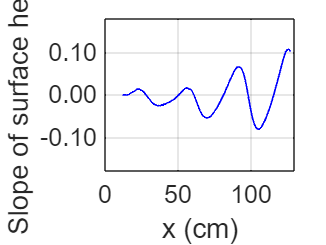

%% Script 1: Slope Across Long Axis for a Specific Frame
tic;

clear 
close all
clc

%% Parameters
date = '09';
rot_rate = 0.4189;
rot_rate = string(rot_rate);
freq_value = 2.2;
freq_value = string(freq_value);
ampl_value = 7;

% Define the base directory for input and output files
input_dir = sprintf('D:\\Matlab\\Matlab input\\202409%s_full_plate_final\\202409%s_%sradps_%sHz_%smm_full_plate_separate_frames\\Results\\', date, date, rot_rate, freq_value, string(ampl_value));
output_dir = sprintf('D:\\Matlab\\Matlab output\\202409%s_full_plate_final_results\\202409%s_%sradps_%sHz_%smm_full_plate\\Trend\\', date, date, rot_rate, freq_value, string(ampl_value));

% Define the base file name and extension
base_file_name = sprintf('202409%s_%sradps_%sHz_%smm_full_plate_frame_', date, rot_rate, freq_value, string(ampl_value));
file_extension = 'A_vel_new.dat';

%% Parameters specific to 'long_axis' mode
frame_num = 280;  % Frame number for slope calculation across long axis

%% Construct the file name for the specified frame
frame_str = sprintf('%04d', frame_num);
file_name = [base_file_name, frame_str, file_extension];
input_file = fullfile(input_dir, file_name);

%% Load the data
dr = loadvec(input_file);

%% Process the data: remove rows and columns with only zeros
dr_new = dr;
dr_new.x(:, all(dr_new.vy == 0, 2)) = [];
dr_new.y(:, all(dr_new.vy == 0, 1)) = [];
dr_new.vx(:, all(dr_new.vx == 0, 1)) = [];
dr_new.vx(all(dr_new.vx == 0, 2), :) = [];
dr_new.vy(:, all(dr_new.vy == 0, 1)) = [];
dr_new.vy(all(dr_new.vy == 0, 2), :) = [];

%% Compute the surface height
h_0 = 150; % Surface-pattern distance in mm
h = surfheight(dr_new, h_0);
surface_height = h.w;

%% Initialize array to store slopes along the long axis
num_long_axis_points = size(surface_height, 1);
slopes = zeros(num_long_axis_points, 1);

%% Calculate slopes along the short axis for each long axis point
for i = 1:num_long_axis_points
    surf_height_short_axis = surface_height(i, :);
    ampl_short_axis = surf_height_short_axis;
    values_short_axis = h.y / 10;  % Convert to cm

    % Linear fit for slope calculation
    p = polyfit(values_short_axis, ampl_short_axis, 1);  
    slopes(i) = p(1);  % Store the slope
end

%% Plot slopes over long axis points
values_long_axis = (h.x / 10) + 5.664;  % Convert to cm
plot(values_long_axis, slopes, 'b', 'LineWidth', 1);
%title(sprintf('Slope over long axis for frame %d', frame_num));
ax = gca; % Get current axes
ax.YAxis.TickLabelFormat = '%.2f'; % Display numbers in decimal format with 3 decimal places
xlim([0,130])
ylim([-0.18,0.18])
xlabel('x (cm)');
ylabel('Slope of surface height');
ax.FontSize = 15;
grid on;




%% Save the plot
%print(gcf, '-depsc', fullfile(output_dir, sprintf('202409%s_%sradps_%sHz_%smm_slope_vs_long_axis_%s.eps', date, rot_rate, freq_value, string(ampl_value), string(frame_num))));
%saveas(gcf, fullfile(output_dir, sprintf('202409%s_%sradps_%sHz_%smm_slope_vs_long_axis_%s.png', date, rot_rate, freq_value, string(ampl_value), string(frame_num))));

toc;

Elapsed time is 4.011889 seconds.


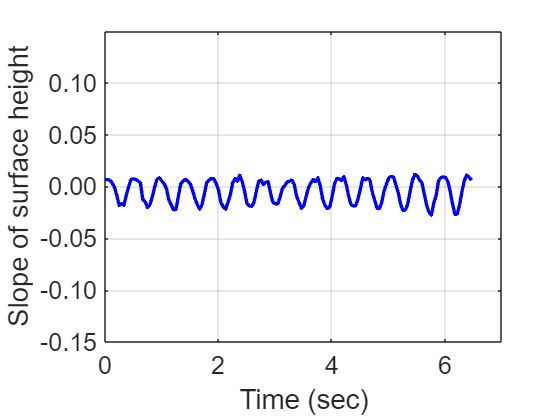

%% Script 2: Slope Over Time at a Specific Long Axis Point
tic;

clear 
close all
clc

%% Parameters
date = '10';
rot_rate = 0;
rot_rate = string(rot_rate);
freq_value = 2.2;
freq_value = string(freq_value);
ampl_value = 7;

% Define the base directory for input and output files
input_dir = sprintf('D:\\Matlab\\Matlab input\\202409%s_full_plate_final\\202409%s_%sradps_%sHz_%smm_full_plate_separate_frames\\Results\\', date, date, rot_rate, freq_value, string(ampl_value));
output_dir = sprintf('D:\\Matlab\\Matlab output\\202409%s_full_plate_final_results\\202409%s_%sradps_%sHz_%smm_full_plate\\Trend\\', date, date, rot_rate, freq_value, string(ampl_value));

% Define the base file name and extension
base_file_name = sprintf('202409%s_%sradps_%sHz_%smm_full_plate_frame_', date, rot_rate, freq_value, string(ampl_value));
file_extension = 'A_vel_new.dat';

%% Parameters specific to 'time' mode
selected_long_axis_point = 170;  % Point on long axis to monitor over time
start_frame = 170;  % Start frame number
end_frame = 325;    % End frame number
frame_rate = 23.98;  % Frame rate in frames per second

%% Initialize array to store slopes for each frame
slopes_over_time = zeros(end_frame - start_frame + 1, 1);

%% Calculate time in seconds for each frame
% frame_numbers = start_frame:end_frame;
% time_in_seconds = (frame_numbers - 1) / frame_rate;
frame_numbers = 1:156;
time_in_seconds = (frame_numbers - 1) / frame_rate;

%% Iterate over each frame to calculate the slope for the selected long axis point
for frame_num = start_frame:end_frame
    % Construct the file name for the current frame
    frame_str = sprintf('%04d', frame_num);
    file_name = [base_file_name, frame_str, file_extension];
    input_file = fullfile(input_dir, file_name);

    % Load the data
    dr = loadvec(input_file);

    % Process the data: remove rows and columns with only zeros
    dr_new = dr;
    dr_new.x(:, all(dr_new.vy == 0, 2)) = [];
    dr_new.y(:, all(dr_new.vy == 0, 1)) = [];
    dr_new.vx(:, all(dr_new.vx == 0, 1)) = [];
    dr_new.vx(all(dr_new.vx == 0, 2), :) = [];
    dr_new.vy(:, all(dr_new.vy == 0, 1)) = [];
    dr_new.vy(all(dr_new.vy == 0, 2), :) = [];

    % Compute the surface height
    h_0 = 150; % Surface-pattern distance in mm
    h = surfheight(dr_new, h_0);
    surface_height = h.w;

    % Surface height on short axis for the selected long axis point
    surf_height_short_axis = surface_height(selected_long_axis_point, :);
    ampl_short_axis = surf_height_short_axis;
    values_short_axis = h.y / 10;  % Convert to cm

    % Linear fit for slope calculation
    p = polyfit(values_short_axis, ampl_short_axis, 1);  
    slopes_over_time(frame_num - start_frame + 1) = p(1);  % Store the slope
end

%% Plot slopes over time (in seconds)
plot(time_in_seconds, slopes_over_time, 'b', 'LineWidth', 2);
%title(sprintf('Slope of surface height %sradps %sHz %smm pos %d', rot_rate, freq_value, string(ampl_value), selected_long_axis_point));
xlabel('Time (sec)');
ylabel('Slope of surface height');
ax = gca; % Get current axes
ax.YAxis.TickLabelFormat = '%.2f'; % Display numbers in decimal format with 3 decimal places
xlim([0,7])
ylim([-0.15,0.15])
ax.FontSize = 15;
grid on;

% %% Compute Peak-to-Peak Amplitude
% max_slope = max(slopes_over_time);  % Maximum slope value
% min_slope = min(slopes_over_time);  % Minimum slope value
% peak_to_peak_amplitude = max_slope - min_slope;
% fprintf('Peak-to-Peak Amplitude: %.4f\n', peak_to_peak_amplitude);
% 
% %% Compute RMS Amplitude
% rms_amplitude = rms(slopes_over_time);  % Root Mean Square of the slopes
% %% Compute Standard Deviation of Slopes
% slope_std_dev = std(slopes_over_time);  % Standard deviation of slope values
% 
% %% Compute Standard Error of RMS (SERMS)
% N = length(slopes_over_time);  % Number of frames
% serms = slope_std_dev / sqrt(N);  % Standard error of the RMS amplitude
% 
% %% Display the values
% fprintf('RMS Amplitude: %.4f\n', rms_amplitude);
% fprintf('Standard Deviation of Slopes: %.4f\n', slope_std_dev);
% fprintf('Standard Error of RMS Amplitude (SERMS): %.4f\n', serms);

%% Save the plot
print(gcf,'-depsc', fullfile(output_dir, sprintf('%sradps_%sHz_%smm_pos_%d_slope_over_time.eps', rot_rate, freq_value, string(ampl_value), selected_long_axis_point)));
saveas(gcf, fullfile(output_dir, sprintf('%sradps_%sHz_%smm_pos_%d_slope_over_time.png', rot_rate, freq_value, string(ampl_value), selected_long_axis_point)));


toc;

Elapsed time is 561.268459 seconds.


% To plot the average slope (averaged out over time/all the frames) as a
% function of the long axis location

tic;

clear 
close all
clc

%% Parameters
ampl_value = 7;
rot_rate = 0.4189;
rot_rate = string(rot_rate);
freq_value = 2.2;
freq_value = string(freq_value);

% Define the base directory for input and output files
input_dir = sprintf('D:\\Matlab\\Matlab input\\20240909_full_plate_final\\20240909_%sradps_%sHz_%smm_full_plate_separate_frames\\Results\\', rot_rate, freq_value, string(ampl_value));
output_dir = sprintf('D:\\Matlab\\Matlab output\\20240909_full_plate_final_results\\20240909_%sradps_%sHz_%smm_full_plate\\Trend\\', rot_rate, freq_value, string(ampl_value));

% Define the base file name and extension
base_file_name = sprintf('20240909_%sradps_%sHz_%smm_full_plate_frame_', rot_rate, freq_value, string(ampl_value));
file_extension = 'A_vel_new.dat';

%% Common Parameters
start_frame = 190;  % Start of frame number for time mode
end_frame = 350;  % End of frame number for time mode
frame_rate = 23.98;  % Frame rate in frames per second

%% Initialize for Averaging Slopes Over Time
% First, we'll compute the slopes for each frame and each long axis point
% Then, we'll average them over time
first_frame_str = sprintf('%04d', start_frame);
first_file_name = [base_file_name, first_frame_str, file_extension];
first_input_file = fullfile(input_dir, first_file_name);

% Load the first frame data to get the dimensions
dr_first = loadvec(first_input_file);
dr_first.x(:, all(dr_first.vy == 0, 2)) = [];
dr_first.y(:, all(dr_first.vy == 0, 1)) = [];
dr_first.vx(:, all(dr_first.vx == 0, 1)) = [];
dr_first.vx(all(dr_first.vx == 0, 2), :) = [];
dr_first.vy(:, all(dr_first.vy == 0, 1)) = [];
dr_first.vy(all(dr_first.vy == 0, 2), :) = [];

% Compute the surface height for the first frame to get the size
h_0 = 150; % surface-pattern distance in mm
h_first = surfheight(dr_first, h_0);
surface_height_first = h_first.w;

% Number of points along the long axis and short axis
num_long_axis_points = size(surface_height_first, 1);
num_short_axis_points = size(surface_height_first, 2);

% Initialize a matrix to accumulate the slopes for each point along the long axis
slope_accumulator = zeros(num_long_axis_points, end_frame - start_frame + 1);

%% Iterate over frames to calculate slopes for each long axis point
for frame_num = start_frame:end_frame
    % Construct the file name for the current frame
    frame_str = sprintf('%04d', frame_num);
    file_name = [base_file_name, frame_str, file_extension];
    input_file = fullfile(input_dir, file_name);

    % Load the data for the current frame
    dr = loadvec(input_file);

    % Process the data: remove rows and columns with only zeros
    dr.x(:, all(dr.vy == 0, 2)) = [];
    dr.y(:, all(dr.vy == 0, 1)) = [];
    dr.vx(:, all(dr.vx == 0, 1)) = [];
    dr.vx(all(dr.vx == 0, 2), :) = [];
    dr.vy(:, all(dr.vy == 0, 1)) = [];
    dr.vy(all(dr.vy == 0, 2), :) = [];

    % Compute the surface height for this frame
    h = surfheight(dr, h_0);
    surface_height = h.w;

    % Calculate the slope along the short axis for each long axis point
    for i = 1:num_long_axis_points
        surf_height_short_axis = surface_height(i, :);
        ampl_short_axis = surf_height_short_axis;
        values_short_axis = h.y / 10;  % Convert to cm
        
        % Linear fit for slope calculation
        p = polyfit(values_short_axis, ampl_short_axis, 1);  
        slope_accumulator(i, frame_num - start_frame + 1) = p(1);  % Store the slope for this frame
    end
end

%% Calculate the average slope over time for each long axis point
average_slope = mean(slope_accumulator, 2);

%% Plot the average slope over the long axis
values_long_axis = h.x / 10;  % Convert to cm
plot(values_long_axis, average_slope, 'b', 'LineWidth', 2);
title('Average Slope over Long Axis (Averaged over Time)');
xlabel('Position on Long Axis (cm)');
ylabel('Average Slope of Surface Height');
grid on;

% Save the plot
saveas(gcf, fullfile(output_dir, sprintf('average_%d_to_%d_slope_vs_long_axis.png',start_frame,end_frame)));

toc;

% % Surface height on short axis
% % Plot the amplitude/surface height over the short axis
% surf_height_short_axis = surface_height(170,:);
% ampl_short_axis = surf_height_short_axis;
% values_short_axis = h.y/10; % in cm
% plot(values_short_axis,surf_height_short_axis)
% title('Surface height over short axis')
% xlabel('Position on short axis (cm)')
% ylabel('Surface height (mm)')
% 
% p = polyfit(values_short_axis, ampl_short_axis, 1);  % Degree 1 for a linear trend
% trendline = polyval(p, values_short_axis);           % Compute the trendline
% plot(values_short_axis, ampl_short_axis, 'b');       % Plot original data
% hold on;
% plot(values_short_axis, trendline, 'r', 'LineWidth', 2);  % Plot the trendline
% hold off;
% slope = p(1)



% output_file_png_surf_height_short = fullfile(output_dir, sprintf('20240909_%sradps_%sHz_%smm_full_plate_surf_height_short_axis_%s.png',rot_rate,freq_value,string(ampl_value), string(frame_num)));
% exportgraphics(gcf, output_file_png_surf_height_short);
% output_file_fig_surf_height_short = fullfile(output_dir, sprintf('20240909_%sradps_%sHz_%smm_full_plate_surf_height_short_axis_%s.fig',rot_rate,freq_value,string(ampl_value), string(frame_num)));
% savefig(gcf, output_file_fig_surf_height_short);

